**PID - ZIGLER NICHOLS**

clc; clear all; close all;

1er Paso, hallar kp = km, 

s = tf('s');
Gs = 10/(s*(s+1)*(s+2))

Gs =
 
         10
  -----------------
  s^3 + 3 s^2 + 2 s
 
Continuous-time transfer function.
Model Properties


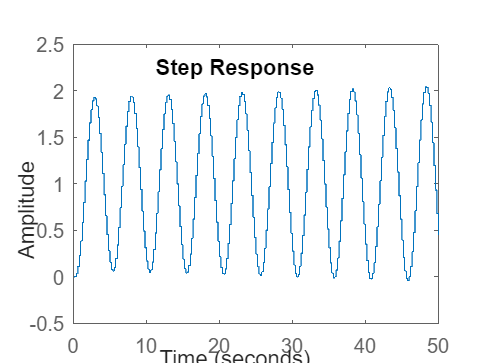

Ts = 0.2;
Gz = c2d(Gs,Ts,'zoh');
km = 0.47;
K = km;
GLCz =feedback(K*Gz,1);
step(GLCz,50)


% Paso 2: hallar la frecuencia de ocilacion
tp2 = 48.2;
tp2 = 43.2;

Tosc = tp2 -tp1;
wm = 2*pi*1/Tosc;
